# Feedforward neural network

## Architecture

Feedforward

NNgenerator_args = struct();
NNgenerator_args.Ninputs = Ninputs;
NNgenerator_args.Noutputs = Noutputs;
NNgenerator_args.NFFlayers = 3;
NNgenerator_args.NRlayers = 0;
NNgenerator_args.NFFneurons = 3*Ninputs;
NNgenerator_args.Nwindow = 1;
NNgenerator_args.hidden_activation = 'reluLayer';
NNgenerator_args.output_activation = 'tanhLayer';
NNgenerator_args.dropout = 0;
NNgenerator_args.WinitFcn = 'narrow-normal';
NNgenerator_args.BinitFcn = 'narrow-normal';
NNgenerator_args.train_bias = false;
NNgenerator_args.scale_data = false;
NNgenerator_args.Xmax = Xmax;
NNgenerator_args.Ymax = Ymax

NNgenerator_args = struct with fields:
              Ninputs: 27
             Noutputs: 5
            NFFlayers: 3
             NRlayers: 0
           NFFneurons: 81
              Nwindow: 1
    hidden_activation: 'reluLayer'
    output_activation: 'tanhLayer'
              dropout: 0
             WinitFcn: 'narrow-normal'
             BinitFcn: 'narrow-normal'
           train_bias: 0
           scale_data: 0
                 Xmax: [27×1 double]
                 Ymax: [5×1 double]


FFnet = NNgenerator(NNgenerator_args);
FFnet = dlupdate(@double, FFnet);

LQR style

LQRLayers = [featureInputLayer(Ninputs, 'Name', 'LQRin')
             fullyConnectedLayer(Ninputs, 'WeightsInitializer', 'narrow-normal')
             batchNormalizationLayer
             tanhLayer
             fullyConnectedLayer(Ninputs, 'WeightsInitializer', 'narrow-normal')
             batchNormalizationLayer
             tanhLayer
             multiplicationLayer(2, 'Name', 'multiplicationLayer')
             fullyConnectedLayer(Noutputs, 'WeightsInitializer', 'narrow-normal')
             tanhLayer
             ];

% Crear el grafo de la red
LQRNet = dlnetwork;
LQRNet = addLayers(LQRNet, LQRLayers);
LQRNet = connectLayers(LQRNet, 'LQRin', 'multiplicationLayer/in2');
LQRNet = dlupdate(@double, LQRNet);

% FFnet = LQRNet

## Training

NNtrain_args = struct();
NNtrain_args.net = FFnet;
NNtrain_args.X_train = dlX_tr;
NNtrain_args.Y_train = dlY_tr;
NNtrain_args.X_val = dlX_val;
NNtrain_args.Y_val = dlY_val;
NNtrain_args.regularization = 0;
NNtrain_args.lr_i = 1e-2;
NNtrain_args.lr_f = 1e-6;
NNtrain_args.plots = 'training-progress'

NNtrain_args = struct with fields:
               net: [1×1 dlnetwork]
           X_train: [27×80000 dlarray]
           Y_train: [5×80000 dlarray]
             X_val: [27×20000 dlarray]
             Y_val: [5×20000 dlarray]
    regularization: 0
              lr_i: 0.0100
              lr_f: 1.0000e-06
             plots: 'training-progress'

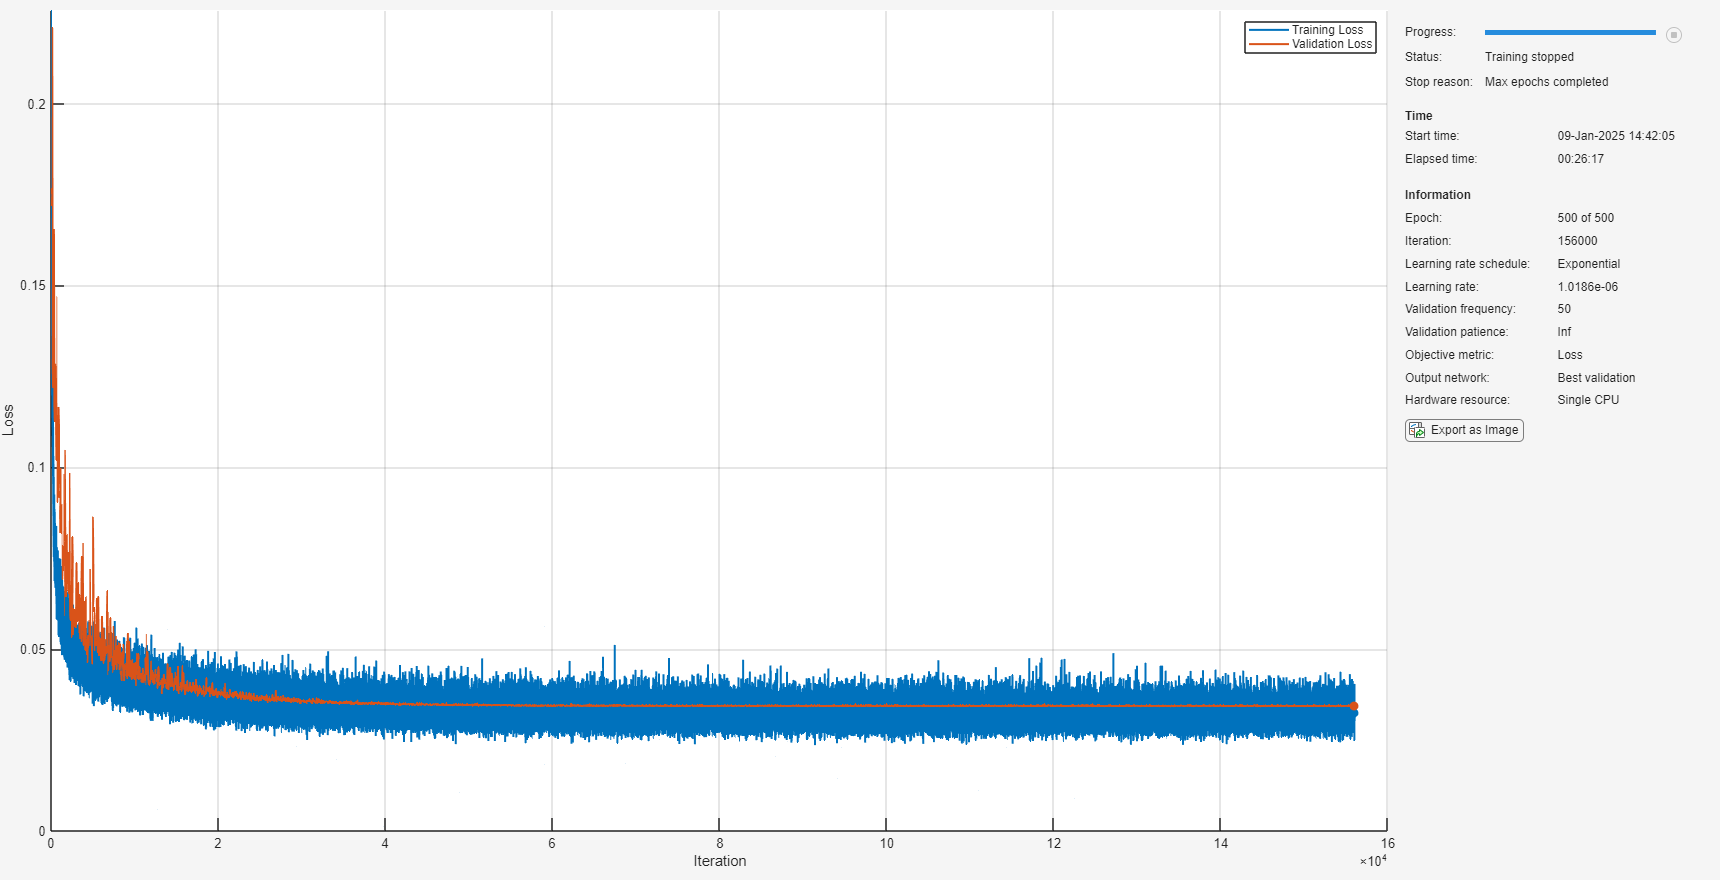

FFnet =   dlnetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     Learnables: [14×3 table]
          State: [6×3 table]
     InputNames: {'input'}
    OutputNames: {'tanhLayer'}
    Initialized: 1
  View summary with summary.


FFnet = NNtrain(NNtrain_args)

save('NeuralNetwork\Imitation\ActualArchitectures\FFnet.mat', "FFnet")

## Summary

dlY_tr_pred = FFnet.predict(dlX_tr);
dlY_val_pred = FFnet.predict(dlX_val);

Y_tr_pred = extractdata(dlY_tr_pred);
Y_val_pred = extractdata(dlY_val_pred);

trainPerformance = mse(dlY_tr_pred, dlY_tr);
valPerformance = mse(dlY_val_pred, dlY_val);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.070118


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.085592


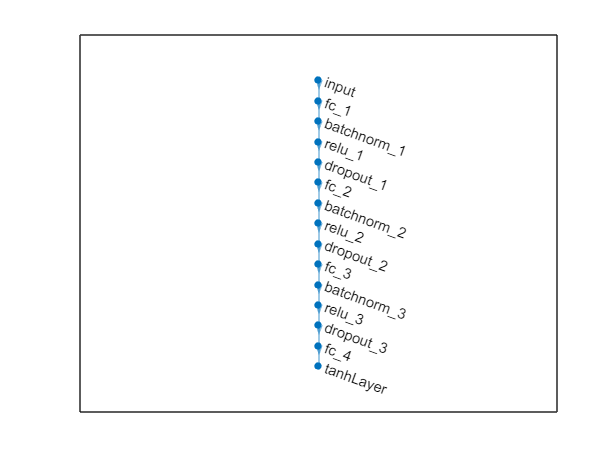


plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)

   Initialized: true
   Number of learnables: 16.4k
   Inputs:
      1   'input'   27 features


# Performance analysis

## Complete timeseries

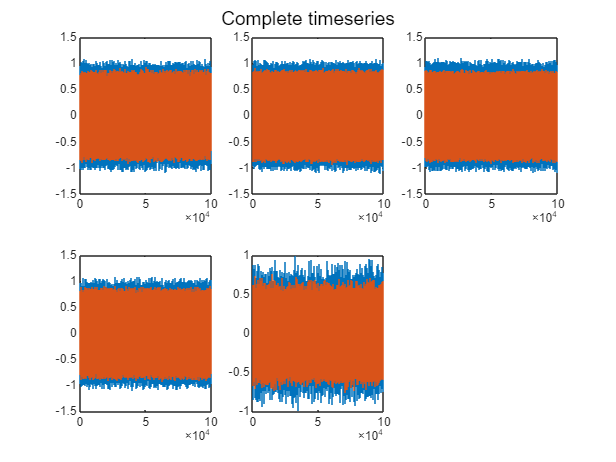

pred = extractdata(FFnet.predict(dlX));
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nsamples, Y(1, :))
hold on
stairs(1:Nsamples, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nsamples, Y(idx, :))
    hold on
    stairs(1:Nsamples, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

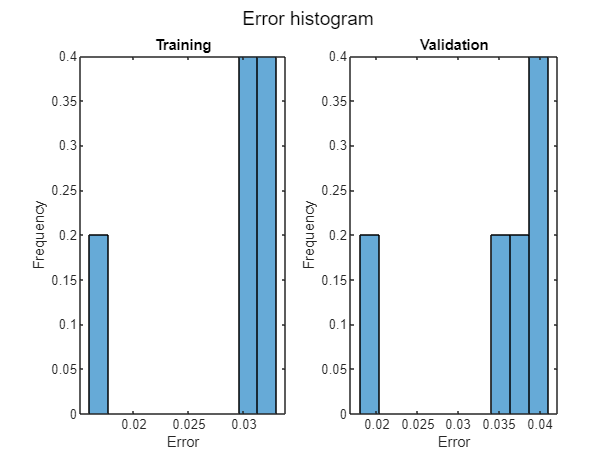

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 10, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 10, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

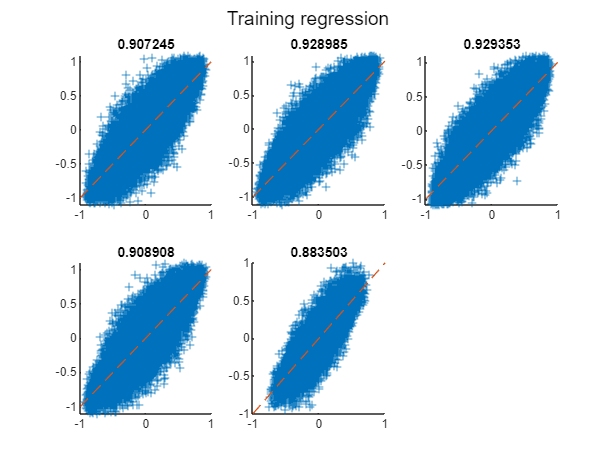

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

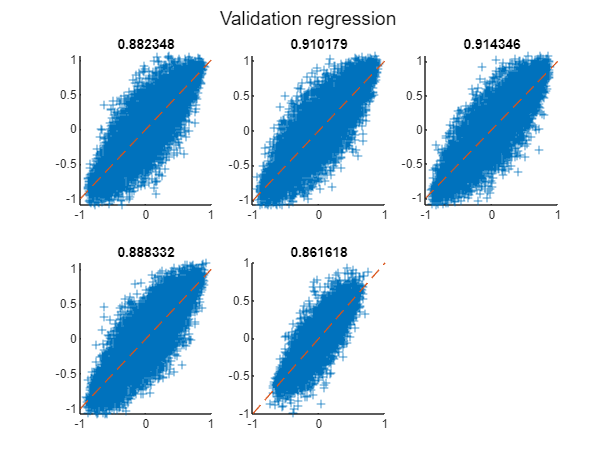


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

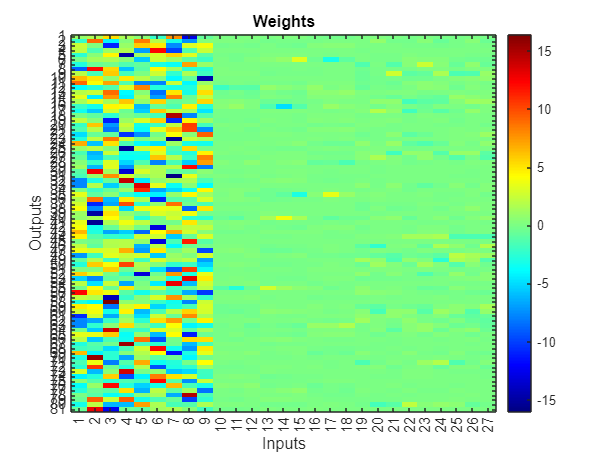

weights_input_hidden = FFnet.Learnables.Value;
weights_input_hidden = extractdata(weights_input_hidden{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(max(abs(weights_input_hidden)))

weights_treshold = 0.1643

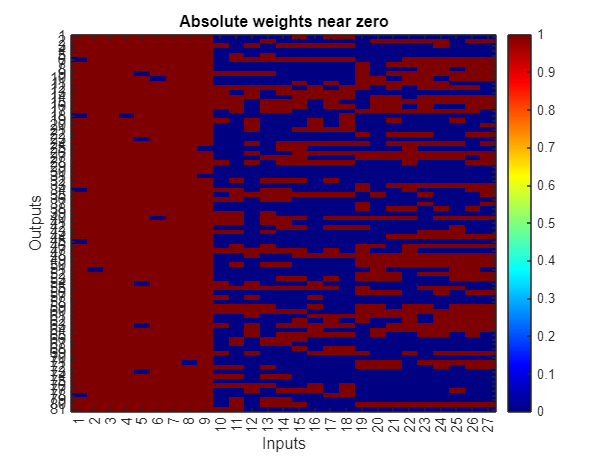

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

# Architecture search

% % Crear carpetas para guardar los resultados
% mkdir('neural_network/results/architectures');
% mkdir('neural_network/results/performance');
% 
% % Definir rango de arquitecturas
% Nlayers_range = 1:10;
% Nneurons_range = 2:2:30;
% 
% % Inicializar matrices para guardar resultados
% results = [];
% 
% % Iterar sobre el rango de arquitecturas
% for Nlayers = Nlayers_range
%     for Nneurons = Nneurons_range
%         try
%             net_name = [num2str(Nlayers) 'L' num2str(Nneurons) 'N'];
% 
%             % Architecture
%             Hactivation = 'tanhLayer';
%             Oactivation = 'tanhLayer';
%             dropout = 0;
%             Winitializer = 'narrow-normal';
%             Binitializer = 'narrow-normal';
%             net = FFNN(Ninputs, Noutputs, Nlayers, Nneurons, Hactivation, Oactivation, dropout, Winitializer, Binitializer).net;
% 
%             % Training
%             regularization = 0*1e-4;
%             lr_i = 1e-2;
%             lr_f = 1e-6;
%             plots = 'none';
%             net = NNtrain(net, X_train, Y_train, X_val, Y_val, regularization, lr_i, lr_f, plots);
% 
%             % Evaluating
%             trainPerformance = mse(net.predict(X_train'), Y_train');
%             valPerformance = mse(net.predict(X_val'), Y_val');
%             diffPerformance = valPerformance - trainPerformance;
% 
%             % Results
%             results = [results; Nlayers, Nneurons, trainPerformance, valPerformance, diffPerformance];
% 
%             % Save net
%             save(fullfile('neural_network/results/architectures', ['A' net_name '.mat']), 'net');            
% 
%         catch ME
%             disp(['Error ' net_name ': ' ME.message]);
%             continue;
%         end
%     end
% end
% csvwrite('neural_network/results/performance/performance.csv', results);

Heatmap

% data = readmatrix('neural_network/results/performance/performance.csv');
% Narchitectures = length(data)
% Nlayers_range = sort(unique(data(:, 1)))'
% Nneurons_range = sort(unique(data(:, 2)))'
% 
% % Performance in percentage
% trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
% valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
% diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;
% 
% z_max = 100;
% trainPerformance(trainPerformance > z_max) = z_max;
% valPerformance(valPerformance > z_max) = z_max;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Train MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Validation MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('(Validation - Train) MSE (%)');
% colorbar;
% colormap jet;

3d Plot

% figure;
% surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% title('Train MSE');
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% title('Validation MSE');
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
% hold on
% surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
% hold off
% 
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance %');
% legend(["Train", "Validation"])
% colorbar;
% colormap jet;
% shading interp;
% 
% figure;
% surf(Nlayers_range, Nneurons_range, diffPerformance, 'EdgeColor', 'none');
% xlabel('Layers');
% ylabel('Neurons/Layer');
% yticks(Nneurons_range)
% zlabel('Performance diference %');
% legend("Validation-Train")
% colorbar;
% colormap jet;
% shading interp;

Tables

% Nbest_architectures = 4;
% 
% valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
% [valid_rows, valid_cols] = find(valid_idx);
% 
% results_table = [];
% for i = 1:length(valid_rows)
%     row = valid_rows(i);
%     col = valid_cols(i);
% 
%     mse_train = trainPerformance(row, col);
%     mse_val = valPerformance(row, col);
%     mse_diff = abs(diffPerformance(row, col));
% 
%     results_table = [results_table; col, row*2, mse_train, mse_val, mse_diff];
% end
% 
% train_table = sortrows(results_table, 3);
% validation_table = sortrows(results_table, 4);
% diff_table = sortrows(results_table, 5);
% 
% train_table = train_table(1:Nbest_architectures, :);
% validation_table = validation_table(1:Nbest_architectures, :);
% diff_table = diff_table(1:Nbest_architectures, :);
% 
% train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
% diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% 
% disp('Tabla de mejores rendimientos en entrenamiento:');
% disp(train_table);
% 
% disp('Tabla de mejores rendimientos en validación:');
% disp(validation_table);
% 
% disp('Tabla de mejores diferencias entre entrenamiento y validación:');
% disp(diff_table);

% load('neural_network/results/architectures/A1L2N.mat', 'net');
% net
% summary(net)
% 
% trainPerformance = mse(net.predict(X_train'), Y_train')*100
% valPerformance = mse(net.predict(X_val'), Y_val')*100
% diffPerformance = (valPerformance - trainPerformance)

% i = 1;
% for Nlayers = Nlayers_range
%     for Nneurons = Nneurons_range
%         load(['neural_network/results/architectures/A' num2str(Nlayers) 'L' num2str(Nneurons) 'N.mat'], 'net');
%         trainPerformance = mse(net.predict(X_train'), Y_train');
%         valPerformance = mse(net.predict(X_val'), Y_val');
%         diffPerformance = (valPerformance - trainPerformance);
%         data(i, 3) = trainPerformance;
%         data(i, 4) = valPerformance;
%         data(i, 5) = diffPerformance;
%         i = i + 1;
%     end
% end
% 
% % Performance in percentage
% trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)])*100;
% valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)])*100;
% diffPerformance = -reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)])*100;
% 
% z_max = 100;
% trainPerformance(trainPerformance > z_max) = z_max;
% valPerformance(valPerformance > z_max) = z_max;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Train MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('Validation MSE (%)');
% colorbar;
% colormap jet;
% 
% figure;
% heatmap(Nlayers_range, Nneurons_range, round(diffPerformance, 4));
% xlabel('Layers');
% ylabel('Neurons/Layer');
% title('(Validation - Train) MSE (%)');
% colorbar;
% colormap jet;

Tables

% Nbest_architectures = 4;
% 
% valid_idx = (trainPerformance < z_max) & (valPerformance < z_max);
% [valid_rows, valid_cols] = find(valid_idx);
% 
% results_table = [];
% for i = 1:length(valid_rows)
%     row = valid_rows(i);
%     col = valid_cols(i);
% 
%     mse_train = trainPerformance(row, col);
%     mse_val = valPerformance(row, col);
%     mse_diff = abs(diffPerformance(row, col));
% 
%     results_table = [results_table; col, row*2, mse_train, mse_val, mse_diff];
% end
% 
% train_table = sortrows(results_table, 3);
% validation_table = sortrows(results_table, 4);
% diff_table = sortrows(results_table, 5);
% 
% train_table = train_table(1:Nbest_architectures, :);
% validation_table = validation_table(1:Nbest_architectures, :);
% diff_table = diff_table(1:Nbest_architectures, :);
% 
% train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Diff'});
% diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Diff'});
% 
% disp('Tabla de mejores rendimientos en entrenamiento:');
% disp(train_table);
% 
% disp('Tabla de mejores rendimientos en validación:');
% disp(validation_table);
% 
% disp('Tabla de mejores diferencias entre entrenamiento y validación:');
% disp(diff_table);